clear;
user=getenv('USERNAME'); %user = 'Guochun Yang';
addpath(genpath('E:\Software\matlab\functions'))
addpath(genpath('C:\softwares\functions'))

datadir = ['C:\Users\' user '\OneDrive - University of Iowa\JiangLab\Experiments\fMRI\fMRI_program\data_all\'];
savedir = [datadir 'analysis_results_33subs_rng\'];

% models = {'base','interaction','septrial','septrial_interaction','addRevSim'};
modelnames = {'base','interaction','sim_mem_pos1','sim_mem_pos1_interaction','addRevSim','sim_mem','sim_mem_interaction'};


load([savedir 'datas.mat']);
imodel = 4;
% for imodel = 1:length(modelnames) %[1:3,5]
savedir_model = [savedir '\' modelnames{imodel}];
load([savedir_model '\Modelresults.mat']);
nsub = size(Modelresults.betas,1);
tb = readtable([savedir_model '\Modelresults.xlsx']);
tb.AIC = [tb.AIC_1,tb.AIC_2];
tb.beta = [tb.beta_1,tb.beta_2];
simPos_all = Modelresults.simPos_all;


## plot the best fitting model parameters

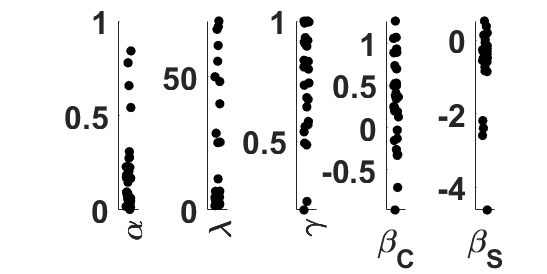

% plot the scatter plot
dotsize = 24;
fontsize = 12;
figure('Position',[400 400 900 450]);
subplot(1,5,1);
plot((rand(nsub,1)-0.5)/20+1,tb.x1,'.k','MarkerSize',dotsize); box off;
%     hold; errorbar(mean(tb.x1),std(tb.x1)/sqrt(nsub-1),'-r','LineWidth',2)
%     line([0.97 1.03],[mean(tb.x1) mean(tb.x1)],'Color','red','lineWidth',2)

xlim([0.9 1.1]); %ylim([0 0.2])
xticks([1]); xticklabels('\alpha')

subplot(1,5,2);
plot((rand(nsub,1)-0.5)/20+1,tb.x2,'.k','MarkerSize',dotsize); box off;
xlim([0.9 1.1]);
xticks([1]); xticklabels('\lambda')

subplot(1,5,3);
plot((rand(nsub,1)-0.5)/20+1,tb.x3,'.k','MarkerSize',dotsize); box off;
xlim([0.9 1.1]); %ylim([0 0.7])
xticks([1]); xticklabels('\gamma')

subplot(1,5,4)
plot((rand(nsub,1)-0.5)/20+1,tb.beta(:,1),'.k','MarkerSize',dotsize); box off;
xlim([0.9 1.1]);
xticks([1]); xticklabels('\beta_C'); xtickangle(0);

subplot(1,5,5)
plot((rand(nsub,1)-0.5)/20+1,tb.beta(:,2),'.k','MarkerSize',dotsize); box off;
xlim([0.9 1.1]);
xticks([1]); xticklabels('\beta_S'); xtickangle(0);

set(findobj(gcf,'type','axes'),'FontSize',24,'FontWeight','Bold');
print('-dpng','-r500',[savedir_model '\optimalparas+modelfitting_reverseS.png'])

## descriptive statistics of model effects

% betas for sim cost, ent and interaction
betas = Modelresults.betas;
for ib = 1:size(betas,2)
    mean_b(ib) = mean(betas(:,ib));
    std_b(ib) = std(betas(:,ib));
    [~,p,~,t] = ttest(betas(:,ib),0);
    ps_b(ib) = p;
    ts_b(ib) = t.tstat;
    ds(ib) = mean_b(ib)/std_b(ib);
    ts = tinv([0.025 0.975],size(betas,1)-1);
    CI(:,ib) = mean_b(ib) + ts*(std_b(ib)/sqrt(size(betas,1)));
end

% number of sim / mem trials
for isub = 1:nsub
    nsims(isub) = length(Modelresults.simtrials{isub});
    nmems(isub) = length(Modelresults.memtrials{isub});
end
mean(nsims)

ans = 93.9091

std(nsims)

ans = 37.1083

min(nsims)

ans = 21

max(nsims)

ans = 166

min(nmems)

ans = 26

max(nmems)

ans = 171

% predict RT
sub = [];
behRT_allsub = [];
predictedRT_allsub = [];

for isub = 1:nsub
    predictedRT = Modelresults.predictedRT(:,isub);
    datas{isub}.predictedRT = predictedRT;
end

% organize the data
for isub = 1:nsub
    data = datas{isub};
    behRT_byBlock = [];
    behACC_byBlock = [];
    behRT_byBlockbyPos = [];
    behACC_byBlockbyPos = [];
    block = data.block;
    RT_select = data.RT_select;
    probetrials = data.probetrials;
    probeSeqs = data.probeSeqs;
    for iblock = 1:max(block)
        blocktrials_RT = intersect(RT_select,find(block == iblock));
        blocktrials_ACC = find(block == iblock);
        behRT_byBlock(iblock) = mean(data.behRT(blocktrials_RT));
        behACC_byBlock(iblock) = mean(data.behCorrect0(blocktrials_ACC));
        predicted_behRT_byBlock(iblock) = mean(data.predictedRT(blocktrials_RT));
        for ipos = 1:5
            postrials_RT = intersect(blocktrials_RT,find(probeSeqs(2,:)==ipos));
            postrials_ACC = intersect(blocktrials_ACC,find(probeSeqs(2,:)==ipos));
            behRT_byBlockbyPos(iblock,ipos) = nanmean(data.behRT(postrials_RT));
            behACC_byBlockbyPos(iblock,ipos) = nanmean(data.behCorrect0(postrials_ACC));
            predicted_behRT_byBlockbyPos(iblock,ipos) = nanmean(data.predictedRT(postrials_RT));

            for iseq = 1:2
                postrials_RT_seq = intersect(intersect(blocktrials_RT,find(probeSeqs(2,:)==ipos)),find(probeSeqs(1,:) == iseq));
                postrials_RT_seq_nums(iblock,ipos,iseq) = length(postrials_RT_seq);
                postrials_ACC_seq = intersect(intersect(blocktrials_ACC,find(probeSeqs(2,:)==ipos)),find(probeSeqs(1,:) == iseq));
                behRT_byBlockbyPosbySeq(iblock,ipos,iseq) = nanmean(data.behRT(postrials_RT_seq));
                behACC_byBlockbyPosbySeq(iblock,ipos,iseq) = nanmean(data.behCorrect0(postrials_ACC_seq));
            end
        end
    end
    behRT_byBlocks(:,isub) = behRT_byBlock;
    predicted_behRT_byBlockbyPoss(:,:,isub) = predicted_behRT_byBlockbyPos;
    predicted_behRT_byBlocks(:,isub) = predicted_behRT_byBlock;
    behRT_byBlockbyPoss(:,:,isub) = behRT_byBlockbyPos;
    behRT_byBlockbyPosbySeqs(:,:,:,isub) = behRT_byBlockbyPosbySeq;
    behACC_byBlocks(:,isub) = behACC_byBlock;
    behACC_byBlockbyPoss(:,:,isub) = behACC_byBlockbyPos;
    behACC_byBlockbyPosbySeqs(:,:,:,isub) = behACC_byBlockbyPosbySeq;

    %     seq_step_trials = [];
    for iseq = 1:2
        for ipos = 1:5
            seq_step_trial_RT = intersect(RT_select,intersect(find(probeSeqs(1,:)==iseq), find(probeSeqs(2,:)==ipos)));
            seq_step_trial_ACC = intersect(find(probeSeqs(1,:)==iseq), find(probeSeqs(2,:)==ipos));
            %             seq_step_trials(iseq,ipos,:) = seq_step_trial;
            ACC_seq_step(iseq,ipos,isub) = nanmean(data.behCorrect0(seq_step_trial_ACC));
            RT_seq_step(iseq,ipos,isub) = nanmean(data.behRT(seq_step_trial_RT));
            predicted_RT_seq_step(iseq,ipos,isub) = nanmean(data.predictedRT(seq_step_trial_RT));
        end
    end
end

% prepare for the plots
behRT_byBlockbyPos_mean = nanmean(behRT_byBlockbyPoss,3);
predicted_behRT_byBlockbyPos_mean = nanmean(predicted_behRT_byBlockbyPoss,3);
behACC_byBlockbyPos_mean = nanmean(behACC_byBlockbyPoss,3);
behER_byBlockbyPos_mean = 1 - behACC_byBlockbyPos_mean;
predicted_behRT_byBlockbyPos_mean = nanmean(predicted_behRT_byBlockbyPoss,3);

behRT_byBlockbyPos_std = nanstd(behRT_byBlockbyPoss,0,3)/sqrt(nsub-1);
predicted_behRT_byBlockbyPos_std = nanstd(predicted_behRT_byBlockbyPoss,0,3)/sqrt(nsub-1);
behER_byBlockbyPos_std = nanstd(behACC_byBlockbyPoss,0,3)/sqrt(nsub-1);


## plot the position effect for different blocks, RT, predRT, ER

f = figure('Position',[0 0 1300 500]);
tiledlayout(1,3,'TileSpacing','Compact','Padding','Compact');
nexttile;
h = errorbar(behRT_byBlockbyPos_mean',behRT_byBlockbyPos_std','-','LineWidth',3); hold;

Current plot held


set(h, {'color'}, {[1 0 0]; [0.8 0 0.2]; [0.6 0 0.4]; [0.4 0 0.6]; [0.2 0 0.8]; [0 0 1]});

xticks([1:1:5]); xlabel('position');
ylabel('RT(s)')
ylim([1 5]); xlim([0.5 5.5])
ax = gca;
set(gca,'FontSize',16);
set(gca,'DefaultTextFontSize',16);
box off;
title('real RT')

nexttile;
%     h = plot(rot90(fliplr(predicted_behRT_byBlockbyPos_mean)),'-','LineWidth',3); hold;
h = errorbar(predicted_behRT_byBlockbyPos_mean',predicted_behRT_byBlockbyPos_std','-','LineWidth',3); hold;

Current plot held


set(h, {'color'}, {[1 0 0]; [0.8 0 0.2]; [0.6 0 0.4]; [0.4 0 0.6]; [0.2 0 0.8]; [0 0 1]});

xticks([1:1:5]); xlabel('position');
ylabel('RT(s)')
ylim([1 5]); xlim([0.5 5.5])

ax = gca;
set(gca,'FontSize',16);
set(gca,'DefaultTextFontSize',16);
box off;
title('predicted RT')

nexttile;
h = errorbar(behER_byBlockbyPos_mean',behER_byBlockbyPos_std','-','LineWidth',3); hold;

Current plot held


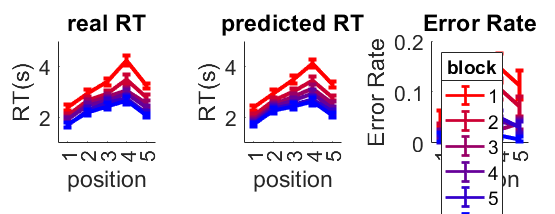

set(h, {'color'}, {[1 0 0]; [0.8 0 0.2]; [0.6 0 0.4]; [0.4 0 0.6]; [0.2 0 0.8]; [0 0 1]});

xticks([1:1:5]); xlabel('position');
ylabel('Error Rate');
% ylim([1 6]);
xlim([0.5 5.5])
hleg = legend({'1','2','3','4','5','6'},'Location','northwest');
title(hleg,'block');
ax = gca;
set(gca,'FontSize',16);
set(gca,'DefaultTextFontSize',16);
box off;
title('Error Rate');

print('-dpng','-r500',[savedir_model,'\RT+modelRT+ER.png'])

Current plot held


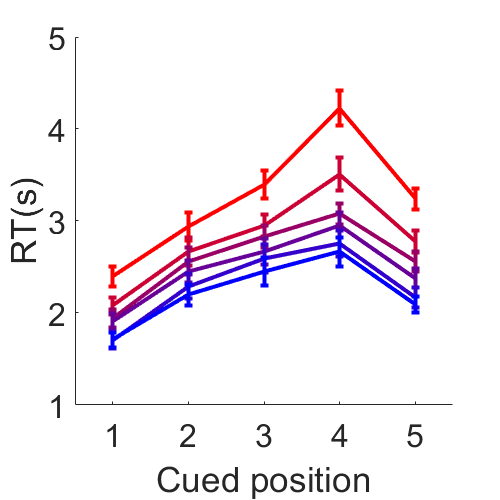

Current plot held


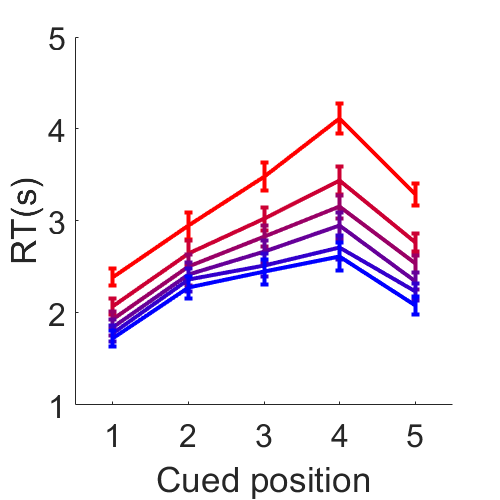

Current plot held


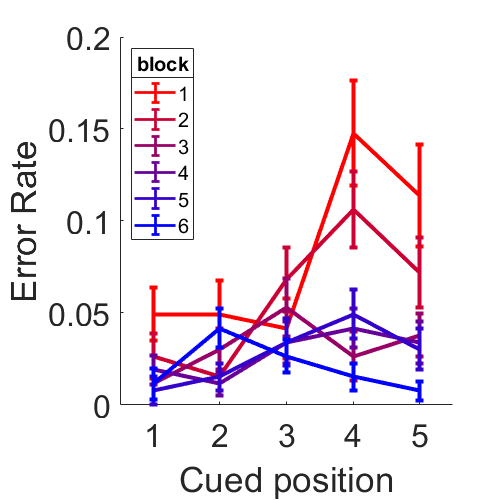

Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held


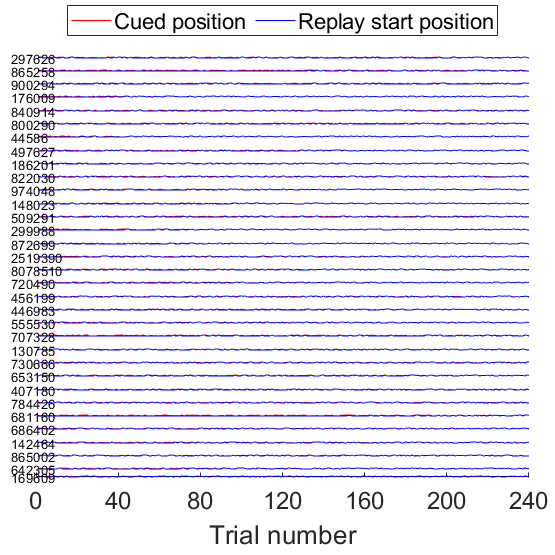

Current plot held


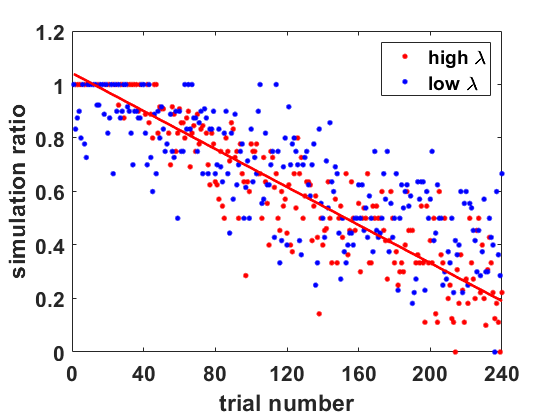

n_sim_frd =    130
   166
   142
    41
   116
   136
    33
    85
    78
   110


tb = 34×6 table
    subs    n_mem    n_sim_frd    n_simfull_frd    n_sim_bkd    n_simfull_bkd
    ____    _____    _________    _____________    _________    _____________

      1       62        130            128             0              0      
      2       26        166            166             0              0      
      3       50        142            142             0              0      
      4      151         41             35             0              0      
      5       76        116            114             0              0      
      6       56        136            136             0              0      
      7      159         33             29             0              0      
      8      107         85             84             0              0      

ans =      1
     2
     3
     5
     6
    10
    13
    20
    22
    24


ans =      4
     7
     8
     9
    11
    12
    14
    15
    16
    17


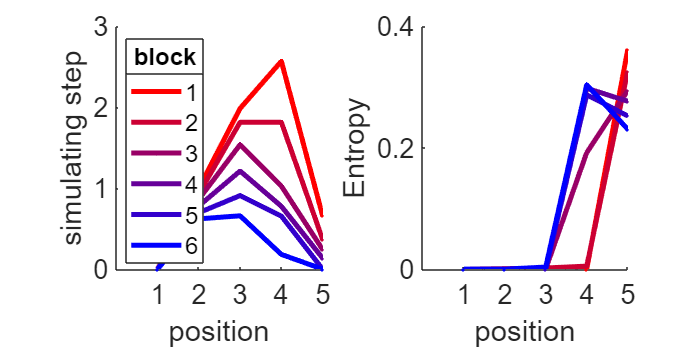

names = {'realRT','predictedRT','ErrorRate'};
ylabels = {'RT(s)','RT(s)','Error Rate'};
for iplot = 1:3
    f = figure('Position',[0 0 500 500]);
    if iplot == 1
        h = errorbar(behRT_byBlockbyPos_mean',behRT_byBlockbyPos_std','-','LineWidth',3); hold;
    elseif iplot == 2
        h = errorbar(predicted_behRT_byBlockbyPos_mean',predicted_behRT_byBlockbyPos_std','-','LineWidth',3); hold;
    else
        h = errorbar(behER_byBlockbyPos_mean',behER_byBlockbyPos_std','-','LineWidth',3); hold;
        hleg = legend({'1','2','3','4','5','6'},'Location','northwest');
        title(hleg,'block');
        set(hleg,'FontSize',15);
    end
    set(h, {'color'}, {[1 0 0]; [0.8 0 0.2]; [0.6 0 0.4]; [0.4 0 0.6]; [0.2 0 0.8]; [0 0 1]});
    
    xticks([1:1:5]); xlabel('Cued position');
    ylabel(ylabels{iplot});
    if iplot < 3; ylim([1 5]); end
    xlim([0.5 5.5])
    ax = gca;
    set(gca,'FontSize',24);
    set(gca,'DefaultTextFontSize',16);
    box off;
    if iplot == 3
        print('-dpng','-r500',[savedir_model,'\',names{iplot},'_withlegend.png']);
    else
        print('-dpng','-r500',[savedir_model,'\',names{iplot},'.png']);
    end
end